# Simulation of Leaky Integrate and Fire (LIF) Neuron with Refractory Period

El = -70e-3; % in mV
Rm = 100e6;  % in megaohms
Cm = 0.1e-9; % in nFarads
tmax = 2;    % in seconds
dt = 0.1e-3;
tvec = 0:dt:tmax;
tref = 2.5e-3;   % in ms
twait = tref/dt; % time must pass before next spike
Vpeak = 50e-3;   % in mV
Vth = -50e-3;    % mV
Vr = -65e-3;     % mV
Iapp = 100e-12:10e-12:600e-12;
Iapp1 = 220e-12; % in pA
Iapp2 = 600e-12; % in pA

## Firing Simulation

fr_1 = zeros(size(Iapp));       % firing rate vector 1
Vvec1 = zeros(size(tvec));      % Membrane Voltage vector 1
mean_V1 = zeros(size(Iapp));    % mean Vm for each current
pltV1 = zeros(2, length(tvec)); % hold two Vm for Iapp1 and Iapp2

% Integrate and Fire Loop
Vvec1(1) = El; % set initial Vm to E leak
for a = 1:length(Iapp) % loop through currents
    spiket1 = zeros(size(tvec)); % store spike times
        for i = 2:length(tvec) % loop through time
            dVdt = ((El - Vvec1(i-1))/Rm + Iapp(a))/Cm; % Euler's Method
            Vvec1(i) = Vvec1(i-1) + dVdt*dt; % update Vm
            % fix Vm at Vr until refractory twait has passed
            if spiket1(i) == -1
                Vvec1(i) = Vr;
            end
            % spike if Vm > Vr
            if Vvec1(i) > Vth
                Vvec1(i) = Vr;
                spiket1(i) = 1;
                for k = 1:twait
                    spiket1(i+k) = -1; % inhibit spiking
                end
            end
        end

% Implement Voltage Peak spiking
    spikecount1 = find(spiket1 == 1);
    for ind = spikecount1
        Vvec1(ind) = Vpeak;
    end
    mean_V1(a) = mean(Vvec1);           % calculate mean voltage for current j
    fr_1(a) = length(spikecount1)/tmax; % update firing rate vector
    % Plot voltage trace for 100ms when Iapp = 220 pA and 600 pA
    if a == 13 % indice for Iapp = 220 pA
        pltV1(1,:) = Vvec1;
    elseif a == 51 % indice for Iapp = 600 pA
        pltV1(2,:) = Vvec1;
    end
end

## Plot Voltage Trace

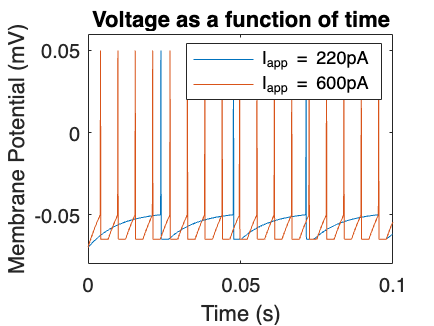

figure;
plot(tvec(:,1:1000), pltV1(1,1:1000), tvec(:,1:1000), pltV1(2,1:1000));
title('Voltage as a function of time');
xlabel('Time (s)');
ylabel('Membrane Potential (mV)');
legend('I_{app} = 220pA', 'I_{app} = 600pA');